close all
clear
clc

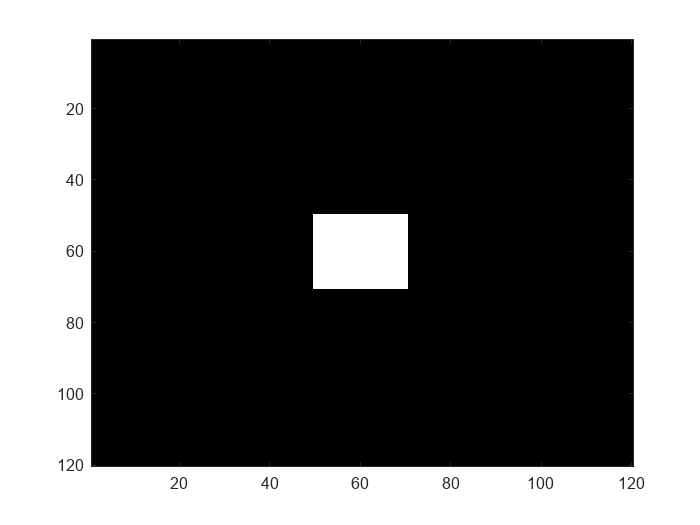

A = zeros(120, 120, 3);
A(size(A)/2-10:size(A)/2+10, size(A)/2-10:size(A)/2+10, :) = 10;
imagesc(A);

x = 60; 
y = 60; 
z = 1;




Ant = ant;
init_voxel = [x, y, z];
Ant.x = x; 
Ant.y = y; 
Ant.z = z;
B = Pheromone_map;
B.A = A;
pheromone_map = B.initialize_matrix();
pheromone = [];
e_death = 1;

tic
for i=1:10000
    pheromone_map(Ant.x, Ant.y, Ant.z, 2) = Ant.mark_voxel(pheromone_map);
    pheromone_map(Ant.x, Ant.y, Ant.z, 1) = Ant.pheromone_release(A);
    pheromone = [pheromone, Ant.pheromone_release(A) - Ant.eta];
    Ant.update_energy(pheromone(i), sum(pheromone)/numel(pheromone))
    if Ant.energy < e_death
        disp('Morte della formica')
        break
    end
    next_voxel = Ant.evaluate_destination(pheromone_map(Ant.x, Ant.y, Ant.z, 1), pheromone_map);
    if isempty(next_voxel) == 1
        disp('Morte della formica')
        break
    end
    pheromone_map(Ant.x, Ant.y, Ant.z, 2) = Ant.leave_voxel(pheromone_map);
end
toc

Elapsed time is 2.693537 seconds.


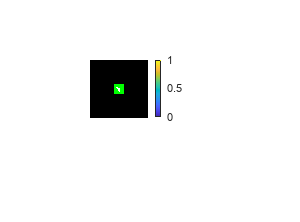

PM = pheromone_map(:, :, :, 1);
imshowpair(A,PM), colorbar;

orthosliceViewer(PM);